% ECE711 - Project
%!! RUN THİS FİRST !!


clc; clear;
% Intialization

Rr  =  1.39e-3;             % ohm, Rotor resistance
Rs  =  1.343e-3;            % ohm, Stator resistance
fb  =  50;                  % Hz, Base frequency
p   =  6;                   % Number of poles
M   =  6;                   % sec, mechanical time constant
Pb  =  1.45e6;              % W, base power
Ib  =  1723*sqrt(2);        % A, base current
we  =  2*pi*fb;             % erad/s, synchronous speed
wmb =  we*(2/p);            % mrad/s, mechanical base speed
Tb  =  13.944e3;            % Nm, rated torque
Vb  = 331.98*sqrt(2);       % V, supply phase peak voltage
J = p/2*Pb*M/(wmb^2);       % inertia


% Impedance and angular speed calculations
Lls     =  0.1044e-3;       % H, Stator inducatnce
Llr     =  0.0498e-3;       % H, Rotor inductance
Lm      =  1.77016e-3;      % H, Magnetizing Inductance 
Lr      = Llr + Lm;

Xls     =  Lls*we;          % Ohm, Stator impedance
Xlr     =  Llr*we;          % Ohm, Rotor impedance
Xm      =  Lm*we;           % Ohm, Magnetizing impedance
wb      =  2*pi*fb;         % rad/s, Base speed
Xmstar  =  1/(1/Xls+1/Xm+1/Xlr);


% part a condition
% slip = 0.0177;
% wrotor = wb*(1-slip);      % rad/s, rotor speed
 
% initial flux voltages
% iqds0_e = (1.0343 - 0.5470i)*Ib;
% iqdr0_e = (-1.0660 + 0.2379i)*Ib;
% 
% iqs0 = real(iqds0_e);  ids0 = -imag(iqds0_e);
% iqr0 = real(iqdr0_e);  idr0 = -imag(iqdr0_e);

% fqs0 = Xls*iqs0 + Xm*(iqr0+iqs0)
% fds0 = Xls*ids0 + Xm*(idr0+ids0)
% fqr0 = Xlr*iqr0 + Xm*(iqs0+iqr0)
% fdr0 = Xlr*idr0 + Xm*(ids0+idr0)

% results obtained from ss operating from simulink
% fqs0 = 3.091496;
% fds0 = 370.160566;
% fqr0 = -76.149885;
% fdr0 = 340.507385;

fqs0 = 0;
fds0 = 0;
fqr0 = 0;
fdr0 = 0;


## Torque Speed Curve

% Tload = linspace(-5*Tb, 5*Tb, 50);               % Nm, load torque
% wr_table = zeros(1, length(Tload))
% for j = 1:length(Tload)
%     sim("Project_RD", 60);
%     wr_table(1,j) = outputVars(length(outputVars),1);
% end
% figure
% plot(wr_table(15:35), Tload(15:35)/Tb)
% xlabel('\omega_{r} [pu]')
% ylabel('Torque [pu]')
% title('Torque-speed characteristics at rated voltage, in linear region')
% yline(0, '--k')
% xline(1, '--k')
% xlim([wr_table(35) wr_table(15)])



## Three Phase Short Circuit Study


% initial slip estimation by ss analysis
slip_init = -0.0072;  % initial slip at rated generator operation at T=-Tb
wrotor_init = wb*(1-slip_init);   % erad/s, initial rotor speed
Tload = -Tb;    % Nm, turbine torque

t_stop = 5;                % s, simulink stop time
t_step = 1e-4;             % s, simulink step time
t_sim = 0:t_step:t_stop;   % s, simulation time
t_f_init = 2.5;            % s, initial time for fault, ss time
t_pu_fault = linspace(0,1,101);  % pu, fault time in a period

t_fault = zeros(1,length(t_pu_fault));  % s, fault time
wr_pu = zeros(length(t_pu_fault),length(t_sim));
Te_pu = zeros(length(t_pu_fault),length(t_sim));
Tload_pu = zeros(length(t_pu_fault),length(t_sim));
Ia_pu = zeros(length(t_pu_fault),length(t_sim));
Ib_pu = zeros(length(t_pu_fault),length(t_sim));
Ic_pu = zeros(length(t_pu_fault),length(t_sim));
Van_pu = zeros(length(t_pu_fault),length(t_sim));
Vbn_pu = zeros(length(t_pu_fault),length(t_sim));
Vcn_pu = zeros(length(t_pu_fault),length(t_sim));


for k = 1:length(t_pu_fault)

    t_fault(k) = t_f_init + 1/fb*t_pu_fault(k);   % sec, fault time
    sim("Project_SC.slx");
    wr_pu(k,:) = outputVars(:,1)';         % pu, rotor speed
    Te_pu(k,:) = outputVars(:,2)';         % pu, machine torque
    Tload_pu(k,:) = outputVars(:,3)';      % pu, load torque
    Ia_pu(k,:) = -outputVars(:,4)';         % pu, phase A current
    Ib_pu(k,:) = -outputVars(:,5)';         % pu, phase B current
    Ic_pu(k,:) = -outputVars(:,6)';         % pu, phase C current
    Van_pu(k,:) = outputVars(:,7)';        % pu, phase An voltage
    Vbn_pu(k,:) = outputVars(:,8)';        % pu, phase Bn voltage
    Vcn_pu(k,:) = outputVars(:,9)';        % pu, phase Cn voltage
end


## Three phase SC Plot when Va is max

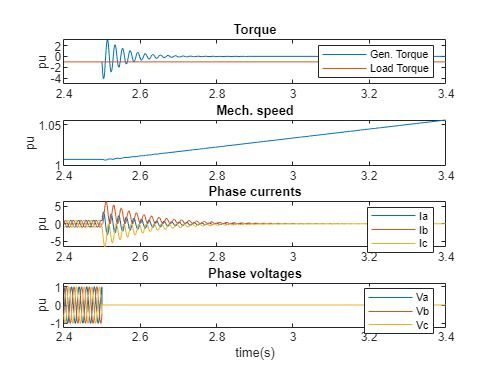

%% fault characteristics when fault is occured when Va is max. and Tload = -Tb

tspan = [2.4 3.4];    % s, time span for plotting
indx = round(tspan(1)/t_step+1:1:tspan(2)/t_step+1);  % time index for plotting

figure; 
subplot(411); plot(t_sim(indx),Te_pu(1,indx),t_sim(indx),Tload_pu(1,indx));
title('Torque'); legend('Gen. Torque','Load Torque'); ylabel('pu')

subplot(412); plot(t_sim(indx),wr_pu(1,indx)); 
title('Mech. speed'); ylabel('pu')

subplot(413); plot(t_sim(indx),Ia_pu(1,indx),t_sim(indx),Ib_pu(1,indx),t_sim(indx),Ic_pu(1,indx));
title('Phase currents'); legend('Ia','Ib','Ic'); ylabel('pu')

subplot(414); plot(t_sim(indx),Van_pu(1,indx),t_sim(indx),Vbn_pu(1,indx),t_sim(indx),Vcn_pu(1,indx)); 
title('Phase voltages'); legend('Va','Vb','Vc'); ylabel('pu'); ylim([-1.2 1.2]); xlabel('time(s)')



% print(gcf, '3phSC_plot_Trated.pdf', '-dpdf', '-fillpage')  % save plot as PDF without margins


## The effect of complex voltage vector angle on SC characteristics

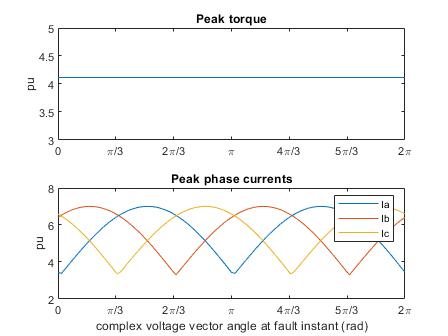


indx2 = round((t_f_init)/t_step+1:1:tspan(2)/t_step+1);  % time index for getting SC characteristics
angle_cv = t_pu_fault*360;                     % deg, angle of the complex voltage vector in SC instant
Te_pu_max = max(abs(Te_pu(:,indx2)),[],2);     % pu, max SC current
Ia_pu_max = max(abs(Ia_pu(:,indx2)),[],2);     % pu, max SC current
Ib_pu_max = max(abs(Ib_pu(:,indx2)),[],2);     % pu, max SC current
Ic_pu_max = max(abs(Ic_pu(:,indx2)),[],2);     % pu, max SC current



figure; 
subplot(211); plot(angle_cv,Te_pu_max)
title('Peak torque'); ylabel('pu'); axis([0 360 3 5]); 
set(gca, 'XTick', 0:60:360); set(gca,'XTickLabel', {'0','\pi/3','2\pi/3','\pi','4\pi/3','5\pi/3','2\pi',})

subplot(212); plot(angle_cv, Ia_pu_max,angle_cv, Ib_pu_max,angle_cv, Ic_pu_max); title('Peak phase currents'); 
legend('Ia','Ib','Ic'); ylabel('pu'); xlabel('complex voltage vector angle at fault instant (rad)'); 
axis([0 360 2 8]); set(gca, 'XTick', 0:60:360); set(gca,'XTickLabel', {'0','\pi/3','2\pi/3','\pi','4\pi/3','5\pi/3','2\pi',})


% print(gcf, '3phSC_angle_dependency', '-dpdf', '-fillpage')  % save plot as PDF without margins

## Two phase SC study  -  AB short circuit



t_fault2 = zeros(1,length(t_pu_fault));  % s, fault time
wr_pu2 = zeros(length(t_pu_fault),length(t_sim));
Te_pu2 = zeros(length(t_pu_fault),length(t_sim));
Tload_pu2 = zeros(length(t_pu_fault),length(t_sim));
Ia_pu2 = zeros(length(t_pu_fault),length(t_sim));
Ib_pu2 = zeros(length(t_pu_fault),length(t_sim));
Ic_pu2 = zeros(length(t_pu_fault),length(t_sim));
Van_pu2 = zeros(length(t_pu_fault),length(t_sim));
Vbn_pu2 = zeros(length(t_pu_fault),length(t_sim));
Vcn_pu2 = zeros(length(t_pu_fault),length(t_sim));


for k = 1:length(t_pu_fault)

    t_fault(k) = t_f_init + 1/fb*t_pu_fault(k);   % sec, fault time
    sim("Project_SC.slx");
    wr_pu2(k,:) = outputVars(:,1)';         % pu, rotor speed
    Te_pu2(k,:) = outputVars(:,2)';         % pu, machine torque
    Tload_pu2(k,:) = outputVars(:,3)';      % pu, load torque
    Ia_pu2(k,:) = -outputVars(:,4)';         % pu, phase A current
    Ib_pu2(k,:) = -outputVars(:,5)';         % pu, phase B current
    Ic_pu2(k,:) = -outputVars(:,6)';         % pu, phase C current
    Van_pu2(k,:) = outputVars(:,7)';        % pu, phase An voltage
    Vbn_pu2(k,:) = outputVars(:,8)';        % pu, phase Bn voltage
    Vcn_pu2(k,:) = outputVars(:,9)';        % pu, phase Cn voltage
end



## Two phase SC Plot when Va is max

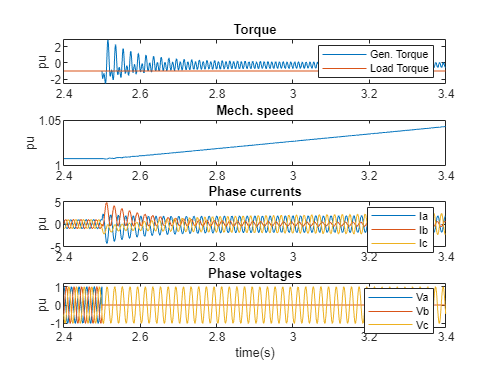

%% two phase fault characteristics when fault is occured when Va is max. and Tload = -Tb

tspan = [2.4 3.4];    % s, time span for plotting
indx = round(tspan(1)/t_step+1:1:tspan(2)/t_step+1);  % time index for plotting

figure; 
subplot(411); plot(t_sim(indx),Te_pu2(1,indx),t_sim(indx),Tload_pu2(1,indx));
title('Torque'); legend('Gen. Torque','Load Torque'); ylabel('pu')

subplot(412); plot(t_sim(indx),wr_pu2(1,indx)); 
title('Mech. speed'); ylabel('pu')

subplot(413); plot(t_sim(indx),Ia_pu2(1,indx),t_sim(indx),Ib_pu2(1,indx),t_sim(indx),Ic_pu2(1,indx));
title('Phase currents'); legend('Ia','Ib','Ic'); ylabel('pu')

subplot(414); plot(t_sim(indx),Van_pu2(1,indx),t_sim(indx),Vbn_pu2(1,indx),t_sim(indx),Vcn_pu2(1,indx)); 
title('Phase voltages'); legend('Va','Vb','Vc'); ylabel('pu'); ylim([-1.2 1.2]); xlabel('time(s)')



% print(gcf, '2phSC_plot_Trated.pdf', '-dpdf', '-fillpage')  % save plot as PDF without margins





## The effect of complex voltage vector angle on two phase SC characteristics

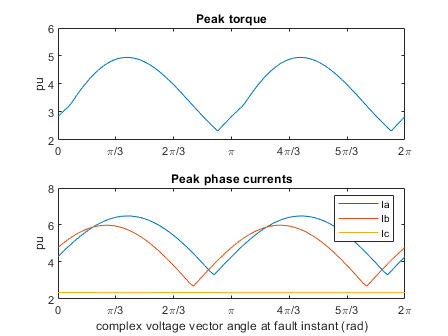


indx2 = round((t_f_init)/t_step+1:1:tspan(2)/t_step+1);  % time index for getting SC characteristics
angle_cv = t_pu_fault*360;              % deg, angle of the complex voltage vector in SC instant
Te_pu_max2 = max(abs(Te_pu2(:,indx2)),[],2);     % pu, max SC current
Ia_pu_max2 = max(abs(Ia_pu2(:,indx2)),[],2);     % pu, max SC current
Ib_pu_max2 = max(abs(Ib_pu2(:,indx2)),[],2);     % pu, max SC current
Ic_pu_max2 = max(abs(Ic_pu2(:,indx2)),[],2);     % pu, max SC current



figure; 
subplot(211); plot(angle_cv,Te_pu_max2)
title('Peak torque'); ylabel('pu'); axis([0 360 2 6]); 
set(gca, 'XTick', 0:60:360); set(gca,'XTickLabel', {'0','\pi/3','2\pi/3','\pi','4\pi/3','5\pi/3','2\pi',})

subplot(212); plot(angle_cv, Ia_pu_max2,angle_cv, Ib_pu_max2,angle_cv, Ic_pu_max2); title('Peak phase currents'); 
legend('Ia','Ib','Ic'); ylabel('pu'); xlabel('complex voltage vector angle at fault instant (rad)'); 
axis([0 360 2 8]); set(gca, 'XTick', 0:60:360); set(gca,'XTickLabel', {'0','\pi/3','2\pi/3','\pi','4\pi/3','5\pi/3','2\pi',})


% print(gcf, '2phSC_angle_dependency', '-dpdf', '-fillpage')  % save plot as PDF without margins